hashTableSizes = [5*1e5 1e6 2*1e6];

N = 1e5;
chars = 'abcdefghijklmnopqrstuvwxyzABCDEFGHIJKLMNOPQRSTUVWXYZ';
i_min = 6;
i_max = 20;
strings = randStringArray(N, i_min, i_max, chars);

resultados = cell(4, 3);
colisoes = zeros(4, 3);
tempos = zeros(4, 3);
codes1 = zeros(4, N);
codes2 = zeros(4, N);
codes3 = zeros(4, N);

% Loop sobre diferentes tamanhos de tabela hash
for i = 1:3
    fprintf("string2hash(djb2): ");
    
    % Inicia a contagem de tempo
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para calcular códigos de hash usando a função 'djb2'
    for j = 1:N
        code = mod(string2hash(strings{j}, 'djb2'), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        % Armazenamento dos resultados nas matrizes correspondentes
        if i == 1
            codes1(1, j) = code;
        elseif i == 2
            codes2(1, j) = code;
        else
            codes3(1, j) = code;
        end
    end

    % Armazenamento dos resultados, contagem de colisões e tempo decorrido
    % (igual ao exercicio passado)
    resultados{1, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(1, i) = numColisoes;
    tempos(1, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(1, i));
    fprintf("------------------------------------------------------------------")
    fprintf("string2hash(sdbm): ");
    
    % Inicia a contagem de tempo
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para calcular códigos de hash usando a função 'sdbm'
    for j = 1:N
        code = mod(string2hash(strings{j}, 'sdbm'), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(2, j) = code;
        elseif i == 2
            codes2(2, j) = code;
        else
            codes3(2, j) = code;
        end
    end

    % Armazenamento dos resultados, contagem de colisões e tempo decorrido
    resultados{2, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(2, i) = numColisoes;
    tempos(2, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(2, i));
    fprintf("------------------------------------------------------------------")
    fprintf("hashstring: ");
    
    % Inicia a contagem de tempo
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para calcular códigos de hash usando a função personalizada 'hashstring'
    for j = 1:N
        code = hashstring(strings{j}, hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(3, j) = code;
        elseif i == 2
            codes2(3, j) = code;
        else
            codes3(3, j) = code;
        end
    end

    % Armazenamento dos resultados, contagem de colisões e tempo decorrido
    resultados{3, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(3, i) = numColisoes;
    tempos(3, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(3, i));
    fprintf("------------------------------------------------------------------")
    fprintf("DJB31MA:\n");
    
    % Inicia a contagem de tempo
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para calcular códigos de hash usando a função 'DJB31MA'
    for j = 1:N
        code = mod(DJB31MA(strings{j}, 13), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(4, j) = code;
        elseif i == 2
            codes2(4, j) = code;
        else
            codes3(4, j) = code;
        end
    end

    % Armazenamento dos resultados, contagem de colisões e tempo decorrido
    resultados{4, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(4, i) = numColisoes;
    tempos(4, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(4, i));
    fprintf("\n\n\n\n\n");
end

string2hash(djb2): 

	Número de colisões para Hash Table de tamanho 500000: 18084


	Elapsed time: 0.096560



------------------------------------------------------------------

string2hash(sdbm): 

	Número de colisões para Hash Table de tamanho 500000: 18184


	Elapsed time: 0.188758



------------------------------------------------------------------

hashstring: 

	Número de colisões para Hash Table de tamanho 500000: 35409


	Elapsed time: 0.772783



------------------------------------------------------------------

DJB31MA:


	Número de colisões para Hash Table de tamanho 500000: 17851


	Elapsed time: 0.081213



string2hash(djb2): 

	Número de colisões para Hash Table de tamanho 1000000: 9710


	Elapsed time: 0.115595



------------------------------------------------------------------

string2hash(sdbm): 

	Número de colisões para Hash Table de tamanho 1000000: 9605


	Elapsed time: 0.166465



------------------------------------------------------------------

hashstring: 

	Número de colisões para Hash Table de tamanho 1000000: 28157


	Elapsed time: 0.682783



------------------------------------------------------------------

DJB31MA:


	Número de colisões para Hash Table de tamanho 1000000: 9286


	Elapsed time: 0.075853



string2hash(djb2): 

	Número de colisões para Hash Table de tamanho 2000000: 4843


	Elapsed time: 0.098913



------------------------------------------------------------------

string2hash(sdbm): 

	Número de colisões para Hash Table de tamanho 2000000: 4923


	Elapsed time: 0.174930



------------------------------------------------------------------

hashstring: 

	Número de colisões para Hash Table de tamanho 2000000: 21954


	Elapsed time: 0.723401



------------------------------------------------------------------

DJB31MA:


	Número de colisões para Hash Table de tamanho 2000000: 4665


	Elapsed time: 0.093775



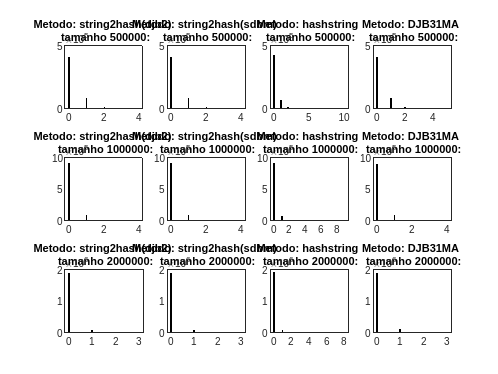


titles = {'string2hash(djb2)', 'string2hash(sdbm)', 'hashstring', 'DJB31MA'};
for i = 1:3
    for j = 1:4
        subplot(3, 4, 4*(i-1)+j);
        histogram(resultados{j, i}, 100);
        title(sprintf("Metodo: %s \n Tamanho: %d:", titles{j}, hashTableSizes(i)));
    end
end

hashTableSizes = [5*1e5 1e6 2*1e6];

N = 1e5;
chars = 'abcdefghijklmnopqrstuvwxyzABCDEFGHIJKLMNOPQRSTUVWXYZ';
i_min = 6;
i_max = 20;
strings = randStringArray(N, i_min, i_max, chars);

resultados = cell(4, 3);
colisoes = zeros(4, 3);
tempos = zeros(4, 3);
codes1 = zeros(4, N);
codes2 = zeros(4, N);
codes3 = zeros(4, N);

% Loop sobre diferentes tamanhos de tabela hash
for i = 1:3
    fprintf("string2hash(djb2):\n");
    
    % Inicia a contagem de tempo
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para calcular códigos de hash usando a função 'djb2'
    for j = 1:N
        code = mod(string2hash(strings{j}, 'djb2'), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        % Armazenamento dos resultados nas matrizes correspondentes
        if i == 1
            codes1(1, j) = code;
        elseif i == 2
            codes2(1, j) = code;
        else
            codes3(1, j) = code;
        end
    end

    % Armazenamento dos resultados, contagem de colisões e tempo decorrido
    resultados{1, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(1, i) = numColisoes;
    tempos(1, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(1, i));
    fprintf("------------------------------------------------------------------")
    fprintf("string2hash(sdbm):\n");
    
    % Inicia a contagem de tempo
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para calcular códigos de hash usando a função 'sdbm'
    for j = 1:N
        code = mod(string2hash(strings{j}, 'sdbm'), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        % Armazenamento dos resultados nas matrizes correspondentes
        if i == 1
            codes1(2, j) = code;
        elseif i == 2
            codes2(2, j) = code;
        else
            codes3(2, j) = code;
        end
    end

    % Armazenamento dos resultados, contagem de colisões e tempo decorrido
    resultados{2, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(2, i) = numColisoes;
    tempos(2, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(2, i));
    fprintf("------------------------------------------------------------------")
    fprintf("hashstring:\n");
    
    % Inicia a contagem de tempo
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para calcular códigos de hash usando a função personalizada 'hashstring'
    for j = 1:N
        code = hashstring(strings{j}, hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        % Armazenamento dos resultados nas matrizes correspondentes
        if i == 1
            codes1(3, j) = code;
        elseif i == 2
            codes2(3, j) = code;
        else
            codes3(3, j) = code;
        end
    end

    % Armazenamento dos resultados, contagem de colisões e tempo decorrido
    resultados{3, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(3, i) = numColisoes;
    tempos(3, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(3, i));
    fprintf("------------------------------------------------------------------")
    fprintf("DJB31MA:\n");
    
    % Inicia a contagem de tempo
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para calcular códigos de hash usando a função 'DJB31MA'
    for j = 1:N
        code = mod(DJB31MA(strings{j}, 13), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        % Armazenamento dos resultados nas matrizes correspondentes
        if i == 1
            codes1(4, j) = code;
        elseif i == 2
            codes2(4, j) = code;
        else
            codes3(4, j) = code;
        end
    end

    % Armazenamento dos resultados, contagem de colisões e tempo decorrido
    resultados{4, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(4, i) = numColisoes;
    tempos(4, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(4, i));
    fprintf("\n\n\n\n");
end

string2hash(djb2):


	Número de colisões para Hash Table de tamanho 500000: 18334


	Elapsed time: 0.094378



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 500000: 17921


	Elapsed time: 0.165382



hashstring:


	Número de colisões para Hash Table de tamanho 500000: 35515


	Elapsed time: 0.750556



DJB31MA:


	Número de colisões para Hash Table de tamanho 500000: 18251


	Elapsed time: 0.078776



string2hash(djb2):


	Número de colisões para Hash Table de tamanho 1000000: 9597


	Elapsed time: 0.110066



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 1000000: 9497


	Elapsed time: 0.176446



hashstring:


	Número de colisões para Hash Table de tamanho 1000000: 28254


	Elapsed time: 0.719642



DJB31MA:


	Número de colisões para Hash Table de tamanho 1000000: 9747


	Elapsed time: 0.084262



string2hash(djb2):


	Número de colisões para Hash Table de tamanho 2000000: 4822


	Elapsed time: 0.110228



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 2000000: 4942


	Elapsed time: 0.186058



hashstring:


	Número de colisões para Hash Table de tamanho 2000000: 22081


	Elapsed time: 0.725720



DJB31MA:


	Número de colisões para Hash Table de tamanho 2000000: 5101


	Elapsed time: 0.092793



Momentos:


	Momento de ordem 2: 2.403200e-01
	Momento de ordem 5: 1.005620e+00
	Momento de ordem 10: 1.364820e+02


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.395320e-01
	Momento de ordem 5: 1.021580e+00
	Momento de ordem 10: 2.104168e+02


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 3.371200e-01
	Momento de ordem 5: 1.277414e+01
	Momento de ordem 10: 9.596330e+04


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.407800e-01
	Momento de ordem 5: 1.062920e+00
	Momento de ordem 10: 1.977166e+02


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 1.100940e-01
	Momento de ordem 5: 2.767000e-01
	Momento de ordem 10: 1.542521e+01


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 1.100120e-01
	Momento de ordem 5: 2.810800e-01
	Momento de ordem 10: 3.055365e+01


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 1.538260e-01
	Momento de ordem 5: 4.657480e+00
	Momento de ordem 10: 2.387379e+04


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 1.102380e-01
	Momento de ordem 5: 2.798800e-01
	Momento de ordem 10: 1.806632e+01


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 5.247400e-02
	Momento de ordem 5: 9.026000e-02
	Momento de ordem 10: 2.489794e+00


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 5.254500e-02
	Momento de ordem 5: 9.231500e-02
	Momento de ordem 10: 3.624495e+00


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 6.953100e-02
	Momento de ordem 5: 1.404695e+00
	Momento de ordem 10: 4.874950e+03


------------------------------------------------------------------------------------------


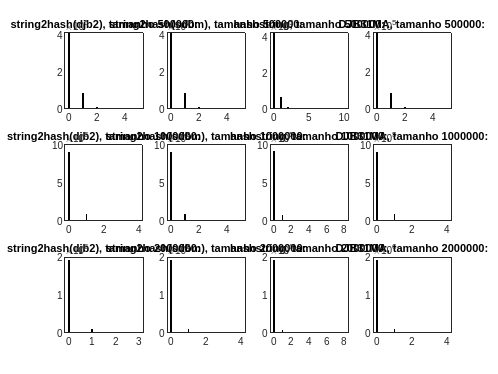

Momentos:


	Momento de ordem 2: 5.262500e-02
	Momento de ordem 5: 9.332000e-02
	Momento de ordem 10: 3.228125e+00


------------------------------------------------------------------------------------------



titles = {'string2hash(djb2)', 'string2hash(sdbm)', 'hashstring', 'DJB31MA'};
momentos = zeros(3, 10);

% Loop para plotar histogramas e calcular momentos
for i = 1:3
    for j = 1:4
        subplot(3, 4, 4*(i-1)+j);
        histogram(resultados{j, i}, 100);
        title(sprintf("%s, tamanho %d:", titles{j}, hashTableSizes(i)));

        fprintf("Momentos:\n");
        valores = resultados{j, i};
        [contagem, valores] = groupcounts(valores);
        
        % Loop para calcular momentos de ordem 2, 5 e 10
        for n = [2, 5, 10]       
            En = 0;
            for x = 1:length(valores)
                En = En + ((valores(x)^n)*(contagem(x)/hashTableSizes(i)));
            end
            momentos(i, n) = En;
            fprintf("\tMomento de ordem %d: %d\n", n, En);
        end
        
        fprintf("\n");
        fprintf("------------------------------------------------------------------------------------------\n")
    end
end

hashTableSizes = [5*1e5 1e6 2*1e6];

N = 1e5;
chars = 'abcdefghijklmnopqrstuvwxyzABCDEFGHIJKLMNOPQRSTUVWXYZ';
i_min = 6;
i_max = 20;
strings = randStringArray(N,i_min,i_max,chars);

resultados = cell(4,3);
colisoes = zeros(4,3);
tempos=zeros(4,3);
codes1 = zeros(4,N);
codes2 = zeros(4,N);
codes3 = zeros(4,N);

% Loop para iterar sobre os tamanhos da tabela hash
for i= 1:3
    fprintf("string2hash(djb2):\n");
    tic;
    hash_table = zeros(hashTableSizes(i),1);
    
    % Loop para iterar sobre as strings geradas
    for j= 1:N
        code = mod(string2hash(strings{j},'djb2'),hashTableSizes(i))+1;
        hash_table(code) = hash_table(code)+1;

        % Atribuição dos códigos de hash às variáveis correspondentes
        if i == 1
            codes1(1,j) = code;
        elseif i == 2
            codes2(1,j) = code;
        else
            codes3(1,j) = code;
        end
    end
    resultados{1,i} = hash_table;
    numColisoes = sum(hash_table(hash_table>1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n",hashTableSizes(i),numColisoes)
    colisoes(1,i) = numColisoes;
    tempos(1,i)=toc;
    fprintf("\tElapsed time: %f\n\n",tempos(1,i));
    fprintf("------------------------------------------------------------------")
    % Repetição similar para as outras funções de hash
    fprintf("string2hash(sdbm):\n");
    tic;
    hash_table = zeros(hashTableSizes(i),1);
    for j= 1:N
        code = mod(string2hash(strings{j},'sdbm'),hashTableSizes(i))+1;
        hash_table(code) = hash_table(code)+1;

        if i == 1
            codes1(2,j) = code;
        elseif i == 2
            codes2(2,j) = code;
        else
            codes3(2,j) = code;
        end
    end
    resultados{2,i} = hash_table;
    numColisoes = sum(hash_table(hash_table>1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n",hashTableSizes(i),numColisoes)
    colisoes(2,i) = numColisoes;
    tempos(2,i)=toc;
    fprintf("\tElapsed time: %f\n\n",tempos(2,i));
    fprintf("------------------------------------------------------------------")
    fprintf("hashstring:\n");
    tic;
    hash_table=zeros(hashTableSizes(i),1);
    for j= 1:N
        code = hashstring(strings{j},hashTableSizes(i))+1;
        hash_table(code) = hash_table(code)+1;

        if i == 1
            codes1(3,j) = code;
        elseif i == 2
            codes2(3,j) = code;
        else
            codes3(3,j) = code;
        end
    end
    resultados{3,i} = hash_table;
    numColisoes = sum(hash_table(hash_table>1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n",hashTableSizes(i),numColisoes)
    colisoes(3,i) = numColisoes;
    tempos(3,i)=toc;
    fprintf("\tElapsed time: %f\n\n",tempos(3,i));
    fprintf("------------------------------------------------------------------")
    fprintf("DJB31MA:\n");
    tic;
    hash_table = zeros(hashTableSizes(i),1);
    for j= 1:N
        code = mod(DJB31MA(strings{j},13),hashTableSizes(i))+1;
        hash_table(code) = hash_table(code)+1;

        if i == 1
            codes1(4,j) = code;
        elseif i == 2
            codes2(4,j) = code;
        else
            codes3(4,j) = code;
        end
    end
    resultados{4,i} = hash_table;
    numColisoes = sum(hash_table(hash_table>1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n",hashTableSizes(i),numColisoes)
    colisoes(4,i) = numColisoes;
    tempos(4,i)=toc;
    fprintf("\tElapsed time: %f\n\n",tempos(4,i));
    fprintf("\n\n\n\n");
end

string2hash(djb2):


	Número de colisões para Hash Table de tamanho 500000: 18164


	Elapsed time: 0.093465



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 500000: 17988


	Elapsed time: 0.165052



hashstring:


	Número de colisões para Hash Table de tamanho 500000: 35507


	Elapsed time: 0.692697



DJB31MA:


	Número de colisões para Hash Table de tamanho 500000: 18142


	Elapsed time: 0.085018



string2hash(djb2):


	Número de colisões para Hash Table de tamanho 1000000: 9548


	Elapsed time: 0.113193



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 1000000: 9546


	Elapsed time: 0.186492



hashstring:


	Número de colisões para Hash Table de tamanho 1000000: 28398


	Elapsed time: 0.716164



DJB31MA:


	Número de colisões para Hash Table de tamanho 1000000: 9550


	Elapsed time: 0.093680



string2hash(djb2):


	Número de colisões para Hash Table de tamanho 2000000: 5009


	Elapsed time: 0.121825



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 2000000: 4807


	Elapsed time: 0.175894



hashstring:


	Número de colisões para Hash Table de tamanho 2000000: 22028


	Elapsed time: 0.738695



DJB31MA:


	Número de colisões para Hash Table de tamanho 2000000: 5006


	Elapsed time: 0.117624



Momentos:


	Momento de ordem 2: 2.400240e-01
	Momento de ordem 5: 1.016840e+00
	Momento de ordem 10: 1.539271e+02


Número de colisões: 18164


Numero máximo de atribuiçoes numa posição: 4


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.396640e-01
	Momento de ordem 5: 1.008140e+00
	Momento de ordem 10: 1.582543e+02


Número de colisões: 17988


Numero máximo de atribuiçoes numa posição: 5


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 3.370800e-01
	Momento de ordem 5: 1.325846e+01
	Momento de ordem 10: 1.436328e+05


Número de colisões: 35507


Numero máximo de atribuiçoes numa posição: 10


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.401880e-01
	Momento de ordem 5: 1.033580e+00
	Momento de ordem 10: 1.868626e+02


Número de colisões: 18142


Numero máximo de atribuiçoes numa posição: 5


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.750750e-02
	Momento de ordem 5: 8.634688e-03
	Momento de ordem 10: 1.737509e-02


Número de colisões: 9548


Numero máximo de atribuiçoes numa posição: 4


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.751600e-02
	Momento de ordem 5: 8.706875e-03
	Momento de ordem 10: 1.804807e-02


Número de colisões: 9546


Numero máximo de atribuiçoes numa posição: 4


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 3.850250e-02
	Momento de ordem 5: 1.521172e-01
	Momento de ordem 10: 4.959825e+01


Número de colisões: 28398


Numero máximo de atribuiçoes numa posição: 10


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.752050e-02
	Momento de ordem 5: 8.750938e-03
	Momento de ordem 10: 1.918440e-02


Número de colisões: 9550


Numero máximo de atribuiçoes numa posição: 4


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 5.841556e-03
	Momento de ordem 5: 3.807613e-04
	Momento de ordem 10: 6.021006e-05


Número de colisões: 5009


Numero máximo de atribuiçoes numa posição: 4


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 5.829778e-03
	Momento de ordem 5: 3.713786e-04
	Momento de ordem 10: 4.258697e-05


Número de colisões: 4807


Numero máximo de atribuiçoes numa posição: 3


------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 7.709111e-03
	Momento de ordem 5: 5.934897e-03
	Momento de ordem 10: 1.708089e-01


Número de colisões: 22028


Numero máximo de atribuiçoes numa posição: 9


------------------------------------------------------------------------------------------


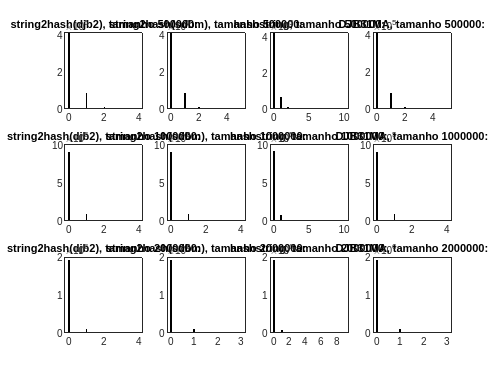

Momentos:


	Momento de ordem 2: 5.843667e-03
	Momento de ordem 5: 3.843416e-04
	Momento de ordem 10: 5.172692e-05


Número de colisões: 5006


Numero máximo de atribuiçoes numa posição: 3


------------------------------------------------------------------------------------------



% Configuração dos títulos para os histogramas
titles={'string2hash(djb2)','string2hash(sdbm)','hashstring','DJB31MA'};
momentos = zeros(3,10);

% Loop para plotar histogramas e calcular momentos
for i= 1:3
    for j= 1:4
        subplot(3,4,4*(i-1)+j);
        histogram(resultados{j,i},100);
        title(sprintf("%s, tamanho %d:",titles{j},hashTableSizes(i)));

        fprintf("Momentos:\n");
        valores = resultados{j,i}/i;
        [contagem,valores] = groupcounts(valores);
        for n= [2,5,10]       
            En = 0;
            for x= 1:length(valores)
                En = En + ((valores(x)^n)*(contagem(x)/hashTableSizes(i)));
            end
            momentos(i,n)=En;
            fprintf("\tMomento de ordem %d: %d\n",n,En);
        end
        
        fprintf("\n");
        fprintf("Número de colisões: %d\n",colisoes(j,i));
        fprintf("Numero máximo de atribuiçoes numa posição: %d\n",max(resultados{j,i}));
        fprintf("\n");
        fprintf("------------------------------------------------------------------------------------------\n")
    end
end

hashTableSizes = [5*1e5 1e6 2*1e6];

N = 1e5;
chars = 'abcdefghijklmnopqrstuvwxyzABCDEFGHIJKLMNOPQRSTUVWXYZ';
i_min = 6;
i_max = 20;
strings = randStringArray(N, i_min, i_max, chars);

resultados = cell(4,3);
colisoes = zeros(4,3);
tempos = zeros(4,3);
codes1 = zeros(4, N);
codes2 = zeros(4, N);
codes3 = zeros(4, N);

% Loop para iterar sobre os tamanhos da tabela hash
for i = 1:3
    fprintf("string2hash(djb2):\n");
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    
    % Loop para iterar sobre as strings geradas
    for j = 1:N
        code = mod(string2hash(strings{j}, 'djb2'), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        % Atribuição dos códigos de hash às variáveis correspondentes
        if i == 1
            codes1(1, j) = code;
        elseif i == 2
            codes2(1, j) = code;
        else
            codes3(1, j) = code;
        end
    end
    resultados{1, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(1, i) = numColisoes;
    tempos(1, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(1, i));
    fprintf("------------------------------------------------------------------")
    % Repetição similar para as outras funções de hash
    fprintf("string2hash(sdbm):\n");
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    for j = 1:N
        code = mod(string2hash(strings{j}, 'sdbm'), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(2, j) = code;
        elseif i == 2
            codes2(2, j) = code;
        else
            codes3(2, j) = code;
        end
    end
    resultados{2, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(2, i) = numColisoes;
    tempos(2, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(2, i));
    fprintf("------------------------------------------------------------------")
    fprintf("hashstring:\n");
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    for j = 1:N
        code = hashstring(strings{j}, hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(3, j) = code;
        elseif i == 2
            codes2(3, j) = code;
        else
            codes3(3, j) = code;
        end
    end
    resultados{3, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(3, i) = numColisoes;
    tempos(3, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(3, i));
    fprintf("------------------------------------------------------------------")
    fprintf("DJB31MA:\n");
    tic;
    hash_table = zeros(hashTableSizes(i), 1);
    for j = 1:N
        code = mod(DJB31MA(strings{j}, 13), hashTableSizes(i)) + 1;
        hash_table(code) = hash_table(code) + 1;

        if i == 1
            codes1(4, j) = code;
        elseif i == 2
            codes2(4, j) = code;
        else
            codes3(4, j) = code;
        end
    end
    resultados{4, i} = hash_table;
    numColisoes = sum(hash_table(hash_table > 1));
    fprintf("\tNúmero de colisões para Hash Table de tamanho %d: %d\n", hashTableSizes(i), numColisoes)
    colisoes(4, i) = numColisoes;
    tempos(4, i) = toc;
    fprintf("\tElapsed time: %f\n\n", tempos(4, i));
    fprintf("\n\n");
end

string2hash(djb2):


	Número de colisões para Hash Table de tamanho 500000: 18322


	Elapsed time: 0.321059



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 500000: 17990


	Elapsed time: 0.377829



hashstring:


	Número de colisões para Hash Table de tamanho 500000: 35617


	Elapsed time: 2.247998



DJB31MA:


	Número de colisões para Hash Table de tamanho 500000: 18404


	Elapsed time: 0.254004



string2hash(djb2):


	Número de colisões para Hash Table de tamanho 1000000: 9650


	Elapsed time: 0.305186



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 1000000: 9449


	Elapsed time: 0.414020



hashstring:


	Número de colisões para Hash Table de tamanho 1000000: 28241


	Elapsed time: 2.694202



DJB31MA:


	Número de colisões para Hash Table de tamanho 1000000: 9425


	Elapsed time: 0.204841



string2hash(djb2):


	Número de colisões para Hash Table de tamanho 2000000: 4903


	Elapsed time: 0.305789



string2hash(sdbm):


	Número de colisões para Hash Table de tamanho 2000000: 4855


	Elapsed time: 0.342694



hashstring:


	Número de colisões para Hash Table de tamanho 2000000: 22113


	Elapsed time: 2.654588



DJB31MA:


	Número de colisões para Hash Table de tamanho 2000000: 4962


	Elapsed time: 0.256839



Momentos:


	Momento de ordem 2: 2.403840e-01
	Momento de ordem 5: 1.026560e+00
	Momento de ordem 10: 1.803299e+02


Número de colisões: 18322


Numero máximo de atribuiçoes numa posição: 5


Tempo de execução: 0.321059

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.402280e-01
	Momento de ordem 5: 1.054280e+00
	Momento de ordem 10: 1.886417e+02


Número de colisões: 17990


Numero máximo de atribuiçoes numa posição: 5


Tempo de execução: 0.377829

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 3.395720e-01
	Momento de ordem 5: 1.408946e+01
	Momento de ordem 10: 1.485587e+05


Número de colisões: 35617


Numero máximo de atribuiçoes numa posição: 10


Tempo de execução: 2.247998

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.406040e-01
	Momento de ordem 5: 1.026500e+00
	Momento de ordem 10: 1.689830e+02


Número de colisões: 18404


Numero máximo de atribuiçoes numa posição: 5


Tempo de execução: 0.254004

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.754050e-02
	Momento de ordem 5: 8.743438e-03
	Momento de ordem 10: 1.798764e-02


Número de colisões: 9650


Numero máximo de atribuiçoes numa posição: 4


Tempo de execução: 0.305186

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.749150e-02
	Momento de ordem 5: 8.673125e-03
	Momento de ordem 10: 1.885317e-02


Número de colisões: 9449


Numero máximo de atribuiçoes numa posição: 4


Tempo de execução: 0.414020

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 3.869750e-02
	Momento de ordem 5: 1.575078e-01
	Momento de ordem 10: 3.692966e+01


Número de colisões: 28241


Numero máximo de atribuiçoes numa posição: 9


Tempo de execução: 2.694202

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 2.749250e-02
	Momento de ordem 5: 8.705000e-03
	Momento de ordem 10: 1.849317e-02


Número de colisões: 9425


Numero máximo de atribuiçoes numa posição: 4


Tempo de execução: 0.204841

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 5.833778e-03
	Momento de ordem 5: 3.711317e-04
	Momento de ordem 10: 3.910640e-05


Número de colisões: 4903


Numero máximo de atribuiçoes numa posição: 3


Tempo de execução: 0.305789

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 5.832222e-03
	Momento de ordem 5: 3.732305e-04
	Momento de ordem 10: 4.970821e-05


Número de colisões: 4855


Numero máximo de atribuiçoes numa posição: 4


Tempo de execução: 0.342694

------------------------------------------------------------------------------------------


Momentos:


	Momento de ordem 2: 7.767444e-03
	Momento de ordem 5: 6.259280e-03
	Momento de ordem 10: 1.112827e-01


Número de colisões: 22113


Numero máximo de atribuiçoes numa posição: 8


Tempo de execução: 2.654588

------------------------------------------------------------------------------------------


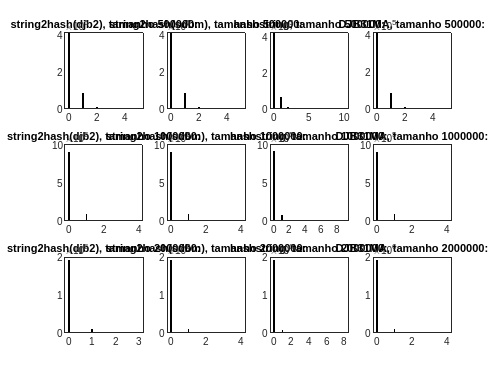

Momentos:


	Momento de ordem 2: 5.840000e-03
	Momento de ordem 5: 3.809465e-04
	Momento de ordem 10: 5.552812e-05


Número de colisões: 4962


Numero máximo de atribuiçoes numa posição: 4


Tempo de execução: 0.256839

------------------------------------------------------------------------------------------



% Configuração dos títulos para os histogramas
titles = {'string2hash(djb2)', 'string2hash(sdbm)', 'hashstring', 'DJB31MA'};
momentos = zeros(3, 10);

% Loop para plotar histogramas e calcular momentos
for i = 1:3
    for j = 1:4
        subplot(3, 4, 4 * (i - 1) + j);
        histogram(resultados{j, i}, 100);
        title(sprintf("Metodo: %s \n tamanho %d:", titles{j}, hashTableSizes(i)));

        fprintf("Momentos:\n");
        valores = resultados{j, i} / i;
        [contagem, valores] = groupcounts(valores);
        for n = [2, 5, 10]       
            En = 0;
            for x = 1:length(valores)
                En = En + ((valores(x)^n) * (contagem(x) / hashTableSizes(i)));
            end
            momentos(i, n) = En;
            fprintf("\tMomento de ordem %d -> %d\n", n, En);
        end

        fprintf("\n");
        fprintf("nº de colisões: %d\n", colisoes(j, i));
        fprintf("nº máx de atribuiçoes numa mesma posição: %d\n", max(resultados{j, i}));
        fprintf("Tempo de execução: %f", tempos(j, i));
        fprintf("\n");
        fprintf("------------------------------------------------------------------------------------------\n")
    end
end